## Task 1

In Task I, you are expected to generate eye diagrams for baseband binary phase shift keying (BPSK) signaling with different pulse shaping filters

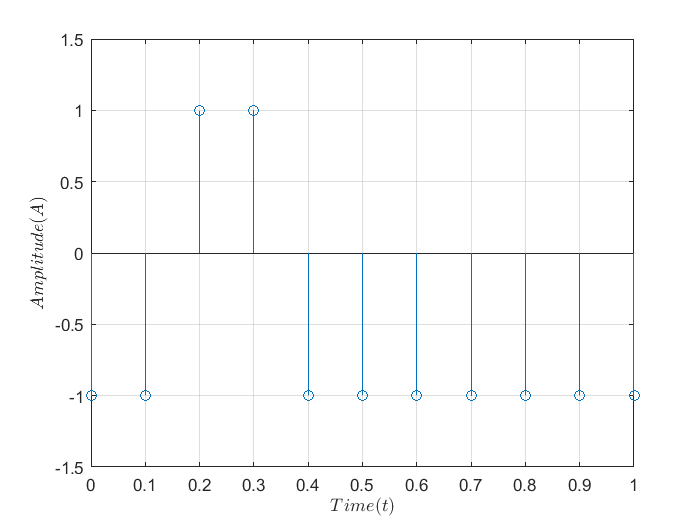

br = 10;      % bit rate of the gnerator 10 bits/second
Tb = 1/br;    % bit duration
L = 1000;     % length of the binary sequence
A = 1;        % amplitude of the impulses

bin_seq = randi([0 1], 1, L);% random binary sequence
time_duration = L*Tb; % time to emmit all the bits in seconds

t_lim = 1;     % limit for the visualization in seconds from the beginning
t = 0:Tb:time_duration -Tb; % time vector

% Mapping binary data into impluses
impulse_train  = zeros(1,L); % impulse train representing BPSK symbols
for index = 1:L
    if bin_seq(index) == 1
        impulse_train(index) = +A;
    else
        impulse_train(index) = -A;
    end
end

stem(t,impulse_train); grid on;
axis([0 t_lim -(3*A/2) (3*A/2)]);
ylabel("$ Amplitude(A)$",'Interpreter','latex');
xlabel("$ Time(t)$",'Interpreter','latex');

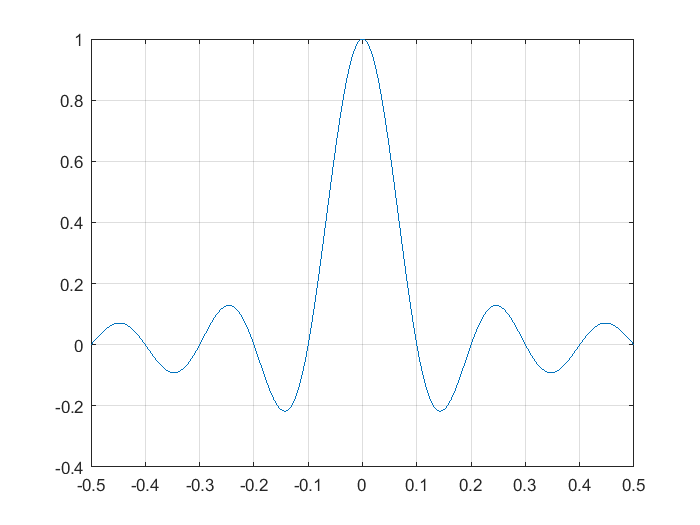

% generating the sinc filter
resolution = 1000; % number of data points to be considered to plot
t_sinc = linspace(-t_lim/2,t_lim/2,resolution);
sinc_pulse = sinc(t_sinc/Tb);
plot(t_sinc, sinc_pulse); grid on;